clear, close all, clc

Anvend den simple lineære regressionsmodel, Y = beta0 + beta1 * x + epsilon. Antag, at der anvendes z = x_bar - x som regressionsvariablen.

Opgave a)

Anvend data fra opgave 11-11 til at lave et scatterplot af (xi,yi) og et andet med (zi = x_bar - xi, yi). Brug de to plots til at forklare, hvordan modellerne Y = beta0 + beta1 * x + epsilon og Y = beta0* + beta1* * z + epsilon hænger sammen.

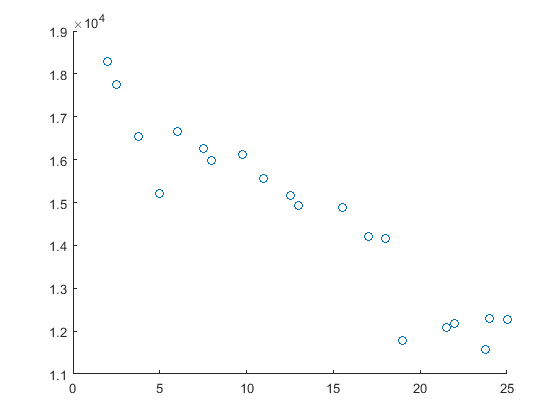

load("dataset_problem_11_11.mat")
scatter(data(:,2),data(:,1))


x_bar = mean(data(:,2))

x_bar = 13.3375

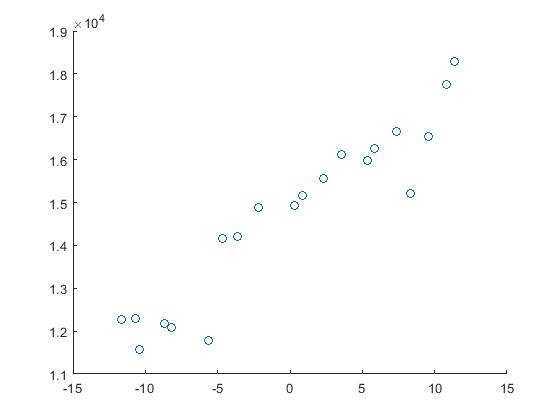


scatter(x_bar-data(:,2),data(:,1))

Opgave b)

Find least-squares-estimaterne af beta0* og beta1* i modellen            Y = beta0* + beta1* * z + epsilon. Hvordan hænger de sammen med estimaterne af beta0_hat og beta1_hat?

[beta,~,r] = regress(data(:,1),[ones(size(data)) x_bar-data(:,2)])

beta = 	1.0e+04 *

         0
    1.4695
    0.0255


r = 	1.0e+03 *

    0.7389
   -0.4744
   -0.0856
    0.4496
   -1.5973
   -1.4756
    0.3239
    0.3008
    0.0760
    0.2692


beta1* = -beta1_hat, beta0* = y_bar